% Load the gTruth file and create training datastore
load("..\gTruth\Semantic Segmentation Data\gTruth Dirty Training\gTruthDirtyTrain.mat")
[imdsTrain, pxdsTrain] = pixelLabelTrainingData(gTruth);

load("..\gTruth\Semantic Segmentation Data\gTruth Dirty Validation\gTruthValidation.mat")
[imdsVal, pxdsVal] = pixelLabelTrainingData(gTruth);

dsTrain = combine(imdsTrain,pxdsTrain);
dsVal = combine(imdsVal,pxdsVal);

% Find class weights
tbl = countEachLabel(pxdsTrain)

tbl = 2×3 table
      Name       PixelCount    ImagePixelCount
    _________    __________    _______________

    {'Frame'}    3.2719e+07      1.5329e+08   
    {'Other'}    1.1935e+08      1.5176e+08   


imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     2.3423
    0.6357


% Create Deeplab V3+ network (Resnet18) 
lgraph = deeplabv3plusLayers([480 640 3],2, "resnet18");

% Balance Classes Using Class Weighting
pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

% Select Training Options
options = trainingOptions('sgdm', ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',dsVal,...
    'MaxEpochs',15, ...  
    'MiniBatchSize',8, ...
    'Shuffle','every-epoch', ...
    'VerboseFrequency',2,...
    'Plots','training-progress',...
    'ValidationPatience', 4);

% Data Augmentation
dsTrain = combine(imdsTrain, pxdsTrain);
xTrans = [-10 10];
yTrans = [-10 10];
dsTrain = transform(dsTrain, @(data)augmentImageAndLabel(data,xTrans,yTrans));

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:02:37 |       54.45% |       70.90% |       0.8942 |       0.5426 |          0.0010 |
|       1 |           2 |       00:03:20 |       72.88% |              |       0.5250 |              |          0.0010 |
|       1 |           4 |       00:04:23 |       83.77% |              |       0.3068 |              |          0.0010 |
|       1 |           6 |       00:05:19 |       87.58% |              |       0.2342 |   

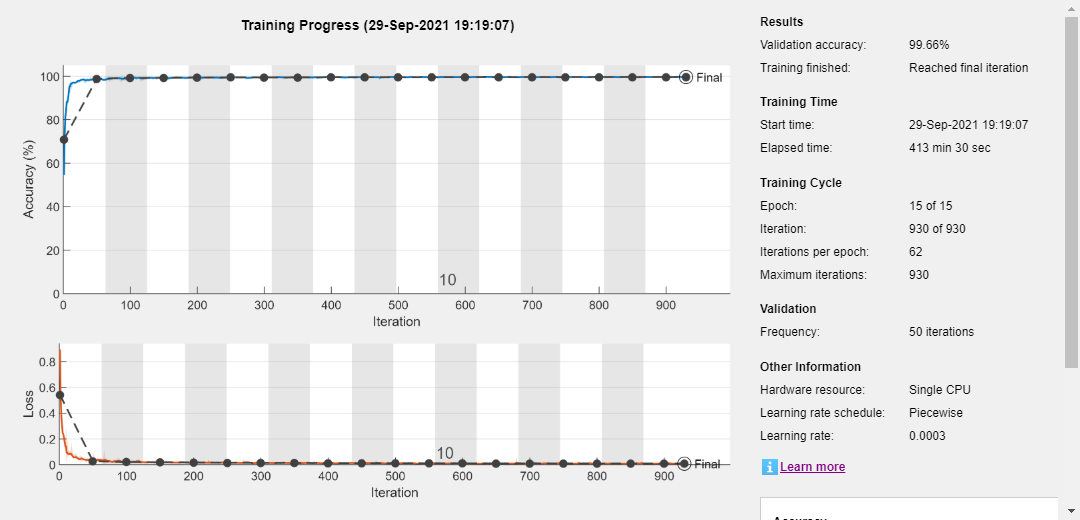

% Train Network
net = trainNetwork(dsTrain, lgraph, options);

DirtyValidNet = net;

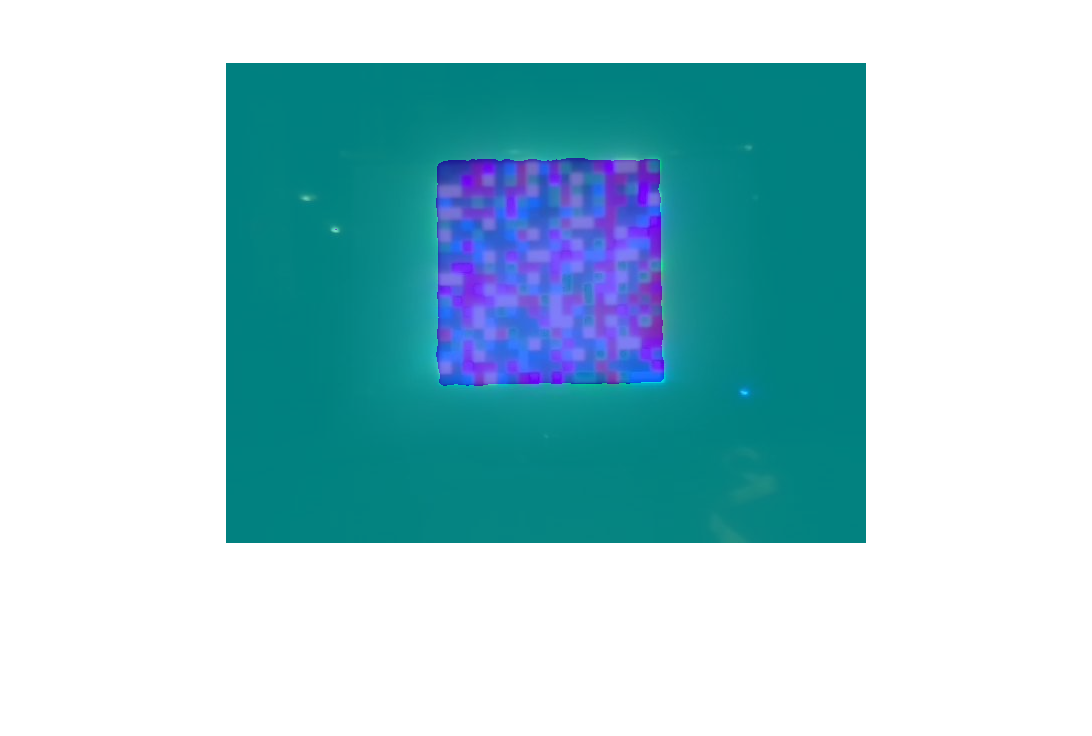

% Test Network on single image
I = imread("..\gTruth\Semantic Segmentation Data\Testing data\47.jpg");
c = semanticseg(I, net);
B = labeloverlay(I,c);
imshow(B)

% Test Network on multiple image
load("..\gTruth\Semantic Segmentation Data\gTruth Dirty Testing\gTruthDirtyTesting.mat")
[imds, pxds] = pixelLabelTrainingData(gTruth);

pxdsResults = semanticseg(imds,net,"WriteLocation",tempdir);

Running semantic segmentation network
-------------------------------------
* Processed 50 images.



metrics = evaluateSemanticSegmentation(pxdsResults,pxds)

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 50 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.99563          0.99585       0.98687      0.99134        0.99265  



metrics =   semanticSegmentationMetrics with properties:

              ConfusionMatrix: [2×2 table]
    NormalizedConfusionMatrix: [2×2 table]
               DataSetMetrics: [1×5 table]
                 ClassMetrics: [2×3 table]
                 ImageMetrics: [50×5 table]


metrics

metrics =   semanticSegmentationMetrics with properties:

              ConfusionMatrix: [2×2 table]
    NormalizedConfusionMatrix: [2×2 table]
               DataSetMetrics: [1×5 table]
                 ClassMetrics: [2×3 table]
                 ImageMetrics: [50×5 table]


metrics.ClassMetrics

ans = 2×3 table
             Accuracy      IoU      MeanBFScore
             ________    _______    ___________

    Frame    0.99622     0.97925      0.98913  
    Other    0.99548      0.9945      0.99617  


metrics.ConfusionMatrix

C = 2×2 table
               Frame         Other   
             __________    __________

    Frame    3.1663e+06         12014
    Other         55093    1.2127e+07


metrics.NormalizedConfusionMatrix

ans = 2×2 table
               Frame        Other  
             _________    _________

    Frame      0.99622    0.0037799
    Other    0.0045226      0.99548


Error using confusionmat (line 50)
At least two inputs are required.

metrics.ImageMetrics
metrics.DataSetMetrics

Error using confusionmat (line 76)
First two arguments must be categorical, numeric, or logical vectors, character arrays, string arrays, or cell arrays of character vectors.